%making the histogram
c210 = c210(:);
clf;
hold on;
LegHandles = []; LegText = {};
[CdfF,CdfX] = ecdf(c210,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(c210,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0 0 1],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'c210 data';
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%making the error bars
elements=[3 14 15 21 24 14 6 2 0  1];
normalizedelements=[0.01 0.046 0.05 0.07 0.08 0.046 0.02 0.006 0  0.003];
bincenters= 16.5:3:43.5;
err=sqrt(elements)/300;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'o');
%making the gaussian fit
pd1 = fitdist(c210, 'normal')

pd1 =   NormalDistribution

  Normal distribution
       mu =   25.93   [24.917, 26.943]
    sigma = 5.10546   [4.48263, 5.93089]


XGrid = XContinuous;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);

LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';
%making the poisson fit
pd2 = fitdist(c210, 'poisson')

pd2 =   PoissonDistribution

  Poisson distribution
    lambda = 25.93   [24.932, 26.928]


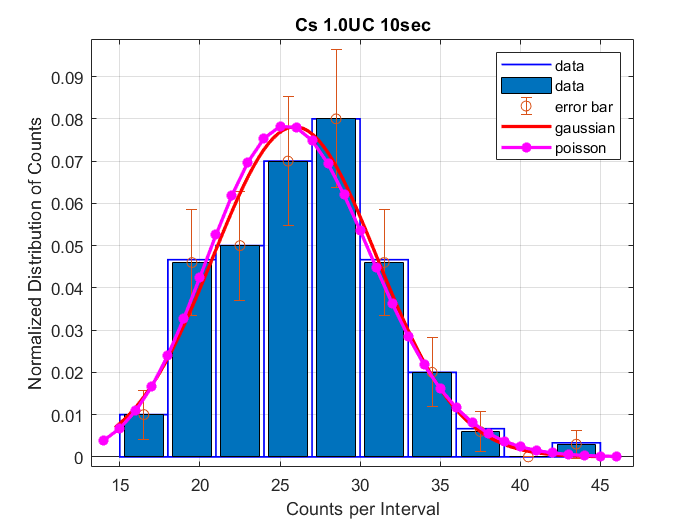

XGrid = XDiscrete;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','*', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';
legend({'data','data','error bar', 'gaussian','poisson'})
box on;
hold off;
xlabel('Counts per Interval')
ylabel('Normalized Distribution of Counts')
grid on

xlim([13.2 47.1])
ylim([-0.0024 0.0989])

title('Cs 1.0UC 10sec')